# Baseball Player Statistics

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

The file `baseballPlayers.txt` contains season statistics for several top offensive baseball players throughout time.

players = readtable("./data/baseballPlayers.csv", "TextType", "string");

## Task 2

The variable `Pos` in the `players` table contains each player's position.

- `1``B`: First Base

- `2``B`: Second Base

- `3``B`: Third Base

- `SS`: Short Stop

- `C`: Catcher

- `LF`: Left Field

- `CF`: Center Field

- `RF`: Right Field

- `OF`: Outfield (general)

- `DH`: Designated Hitter

Which position is most represented in the data?

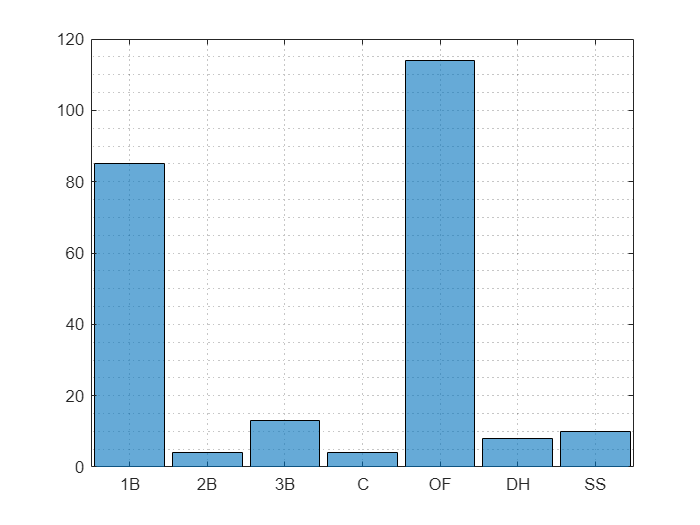

players.Pos = mergecats(categorical(players.Pos), ["OF" "LF" "CF" "RF"], "OF");
histogram(players.Pos)
grid minor

## Task 3

*Runs created* is a statistic used in baseball to estimate the number of team runs an individual contributed to.


$$\mathrm{RC}=\frac{A\;X\;B}{C}$$


*A* = `H` `+` `BB`

*B* = `TB`

*C* = `AB` `+` `BB`

The variables `H` (hits), `BB` (base on balls), and `AB` (at bat) are all in `players`.

`TB` (total bases) must be caculated from other variables found in `players`.

`TB` `=` `H` `+` `B2` `+` `2``*``B3` `+` `3``*``HR`

The variables `B2` (double, more commonly abbreviated as “2B”), `B3` (triple, more commonly abbreviated as “3B”), and `HR` (homerun) are all in `players`.

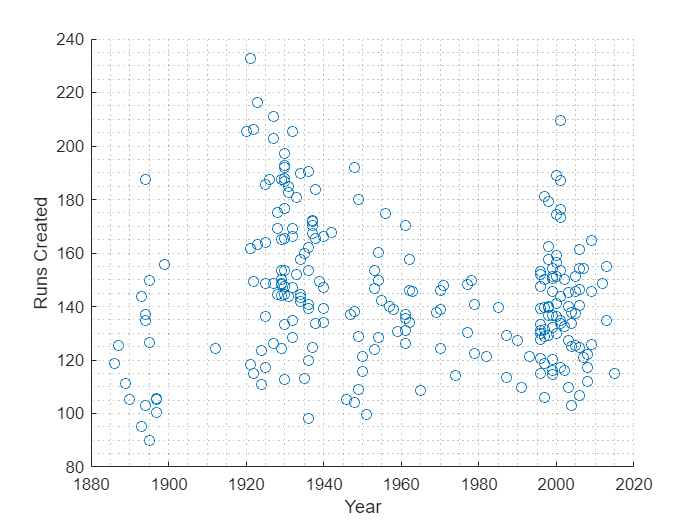

players.TB = players.H + players.B2 + 2*players.B3 + 3*players.HR;
players.RC = (players.H + players.BB).*players.TB ./ (players.AB + players.BB);
scatter(players.Year, players.RC)
grid minor
xlabel("Year")
ylabel("Runs Created")

## Task 4

The “live-ball era” started in 1920. Many factors around this time contributed to increased hitting statistics.

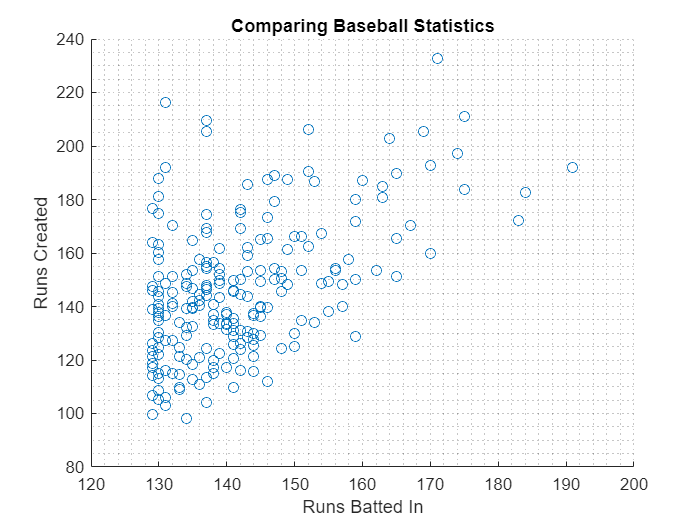

lbEra = players.Year >= 1920;
lbPlayers = players(lbEra, :);
scatter(lbPlayers.RBI, lbPlayers.RC)
grid minor
xlabel("Runs Batted In")
ylabel("Runs Created")
title("Comparing Baseball Statistics")

## Task 5

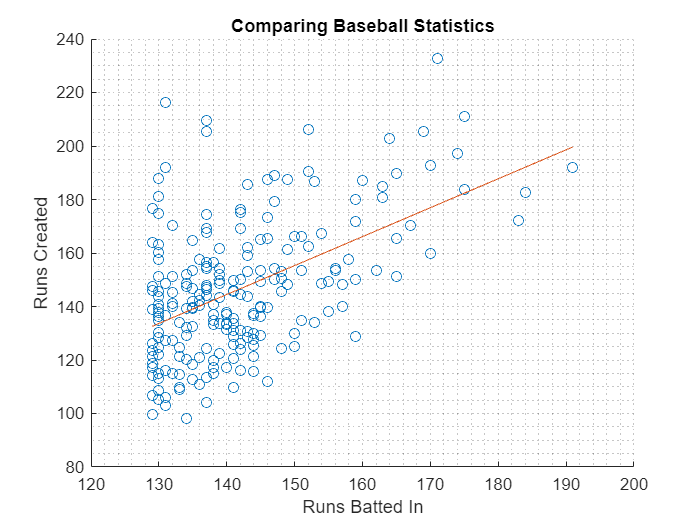

c = polyfit(lbPlayers.RBI, lbPlayers.RC, 1);
RBIfit = [min(lbPlayers.RBI) max(lbPlayers.RBI)];
RCfit = polyval(c, RBIfit);
hold on
plot(RBIfit, RCfit)
hold off